syms x1(t) y1(t) x2(t) y2(t) X2 Y
m1 = 0.1

m1 = 0.1000

m2 = 0.5

m2 = 0.5000

g = 9.8

g = 9.8000

lambda1 = 1

lambda1 = 1

lambda2 = 1

lambda2 = 1

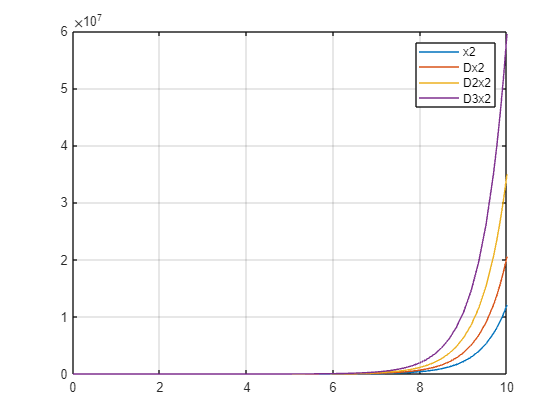

Df = diff(x2,t);
D2f = diff(x2,t,2);
D3f = diff(x2,t,3);
D4f = diff(x2,t,4);
ode = m1*m2*D4f + 2*m1*lambda1*D2f - (lambda2^2)*x2 - m1*lambda2*g == 0;
% cond1 = f(0)==0.4;
% cond2 = Df(0)==0;
% cond3 = D2f(0) == 0;
% cond4 = D3f(0) == 0;
[VF,Sbs] = odeToVectorField(ode);   
odefcn = matlabFunction(VF, 'Vars',{t,Y});
[X2,Y] = ode45(odefcn, [0 10], [0.4 0 0 0]);
figure
plot(X2, Y)
grid
legend(string(Sbs))